clc
clear all
close all

## Parameters

Kernel = 'polynomial';
KernelScale = 1.45;%1.4;
Direction = 'forward';

%AT/PT polynomial 1.45 forward 92.9%
%PT 40 polynomial 1.2 backward 84.2%
%PT 3 polynomial 1.2 backward 89.7%

## LOAD DATA

[Dataset] = load_dataset(0); %1 if you want to detect outliers
%writetable(Dataset,'Dataset.csv');

## FEATURE SELECTION

Data = Dataset{:,1:end-1};
%Data(25,:) = [];
Labels = [zeros(14,1) ; ones(14,1)]; %MODIFICARE IN BASE AL DATASET

Sequential


%c = cvpartition(Labels,'Holdout',0.3); %partiziono dataset 0,3 e' il 30% del dataset come il testset
c = cvpartition(Labels,'LeaveOut');
opts = statset('display','iter');

classf = @(train_data,train_labels,test_data,test_labels) ...
        sum(predict(fitcsvm(train_data,train_labels,'KernelFunction', Kernel, ...
        'PolynomialOrder', [], ...
        'KernelScale', KernelScale, ... 
        'BoxConstraint', 1, ...
        'Standardize', true), test_data) ~= test_labels); 
[fs,history] = sequentialfs(classf,Data,Labels,'cv',c,'options',opts,'direction',Direction);

Start forward sequential feature selection:
Initial columns included:  none
Columns that can not be included:  none
Step 1, added column 18, criterion value 0.25
Step 2, added column 6, criterion value 0.214286
Step 3, added column 1, criterion value 0.178571
Step 4, added column 16, criterion value 0.107143
Step 5, added column 10, criterion value 0.0714286
Final columns included:  1 6 10 16 18 



%}

Fscnca

% mdl = fscnca(Dataset{:,1:end-1},Dataset{:,end});
% figure(1)
% plot(mdl.FeatureWeights,'ro')
% grid on
% xlabel('Feature index')
% ylabel('Feature weight')

Relieff

% [ranks,weights] = relieff(Dataset{:,1:end-1},Dataset{:,end},10);
% 
% %Create a bar plot of predictor importance weights.
% bar(weights(ranks))
% xlabel('Predictor rank')
% ylabel('Predictor importance weight')

Dimensionality reduction

% 3 mesi
%fs = boolean([ 0   0   1   0   0   0   1   1   0   0   1   1   0   1   0   1   0   0]);
% 40 settimane
%fs = boolean([ 0   1   0   0   0   1   0   1   0   1   0   1   1   1   1   0   0   0]);


Dataset =  [ Dataset(:,fs) Dataset(:,end)]; 
fprintf('Sono state selezionate le features: %s');

Sono state selezionate le features: 

Dataset.Properties.VariableNames

ans = 1×6 cell array
    {'VelHandsCorrelation'}    {'JerkFeetCorrelation'}    {'Area_Nose'}    {'Periodicity_Nose'}    {'Periodicity_Feet'}    {'Labels'}


%ELIMINO  PERCHE OUTLIER
%Dataset(25,:) = [];


## TRAINING

trainedClassifier = struct with fields:
    RequiredVariables: {28×1 cell}


Failed prediction of ITEM number 5
Failed prediction of ITEM number 10


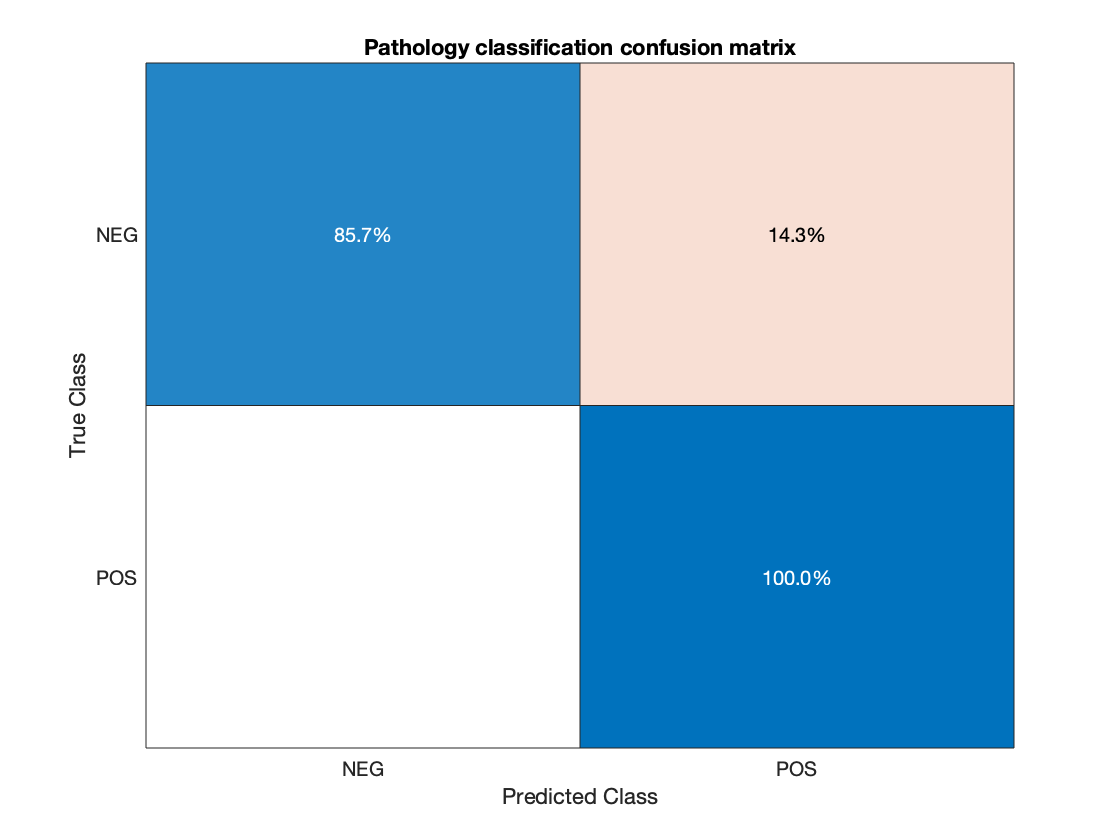

AUC = 0.9439

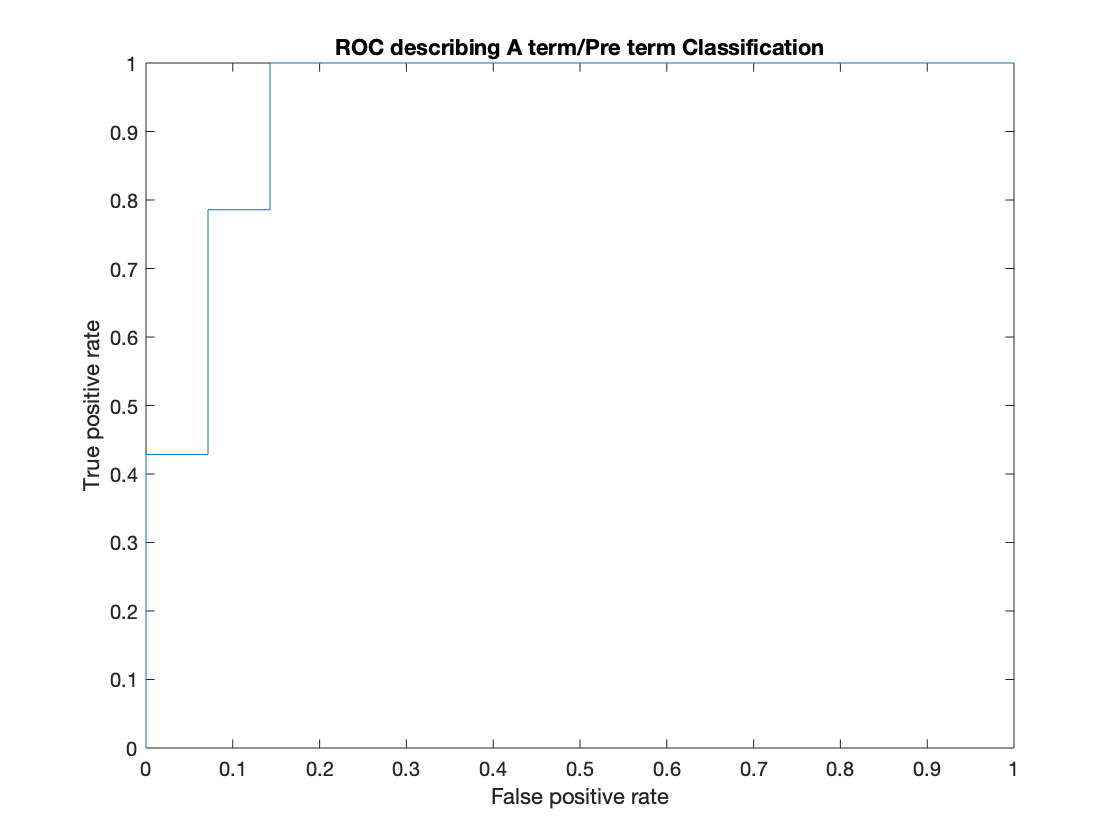


[trainedClassifier, validationAccuracy] = trainClassifier(Dataset,Kernel,KernelScale);


fprintf('The Trainig accuracy is %.1f%% \n',validationAccuracy*100);

The Trainig accuracy is 92.9% 
